% a04_p3_plot_parameters.mlx

% plotting parameters **using individual best-fitting model**

% plot1: plot delta_mu, errorbar = 1SE (68%CI) across subjects for each
% session 

% plot1.5: can check the best-fitting parameters by plugging in sub, sess

% plot2: plot individual PSS/slope, errorbar = 1SE (68%CI) across sessions
% for each sub

% plot3: plot delta_sigma

% plot4: plot delta_criterion


## exclude sub5: extract key parameters from the best fitting model

clear all; close all; clc; rng(1);

% set data path
currentDir = pwd;
exptDir = currentDir(1:regexp(pwd,'03expCode')-1);
outDir = [exptDir '02figures/fig4_best_model_prediction'];
addpath(genpath([exptDir '03ExpCode/05functions']));
addpath(genpath([exptDir '03ExpCode/01pretest/data']));
addpath(genpath([exptDir '03ExpCode/04posttest/data']));
addpath('./model_comparison_function_v5')

load('mc_results_v5_n10.mat')
load('RandomAdaptorOrder.mat' );

% extract the best model across 9 sessions based on delta_AIC
[row col] = find(deltaAIC == 0);
perBestModel = NaN(1,n_all_sub);
perBestModel(row) = col;

% define subjects and sessions to use
sub_slc = [1:4,6:10]; % exclude sub5
all_adaptor = 1:9;
adaptor_soa = [-700, -300, -200, -100,  0,  100, 200, 300, 700];

% pre-allocate
[delta_mu,mu_pre,sigma_pre,delta_sigma, delta_c] = deal(NaN(sub_slc(end), all_adaptor(end)));

for sub = sub_slc
    bestModel = perBestModel(sub);

    % sort by adaptor soa
    i_adaptor_soa = randomAdaptorOrder(sub,:);
    [sorted_adaptor_soa, order] = sort(i_adaptor_soa);

    counter = 1;
    for sess = order
        switch bestModel
            case 1 % M1
                % delta_mu = post_mu - pre_mu
                delta_mu(sub,counter) = estP{sub}{sess,bestModel}(2) - estP{sub}{sess,bestModel}(1);
                % pre_mu, pre_sigma
                mu_pre(sub,counter) = estP{sub}{sess,bestModel}(1);
                sigma_pre(sub,counter) = estP{sub}{sess,bestModel}(3);
                % delta_sigma
                delta_sigma(sub,counter) = estP{sub}{sess,bestModel}(4) - estP{sub}{sess,bestModel}(3);
                % delta_criterion
                delta_c(sub,counter) = estP{sub}{sess,bestModel}(6) - estP{sub}{sess,bestModel}(5);
            case 2 % M2
                % delta_mu = post_mu - pre_mu
                delta_mu(sub,counter) = estP{sub}{sess,bestModel}(2) - estP{sub}{sess,bestModel}(1);
                % pre_mu, pre_sigma
                mu_pre(sub,counter) = estP{sub}{sess,bestModel}(1);
                sigma_pre(sub,counter) = estP{sub}{sess,bestModel}(3); % only 1 sigma
                % delta_sigma
                delta_sigma(sub,counter) = estP{sub}{sess,bestModel}(3) - estP{sub}{sess,bestModel}(3); % only 1 sigma so should be 0
                % delta_criterion
                delta_c(sub,counter) = estP{sub}{sess,bestModel}(5) - estP{sub}{sess,bestModel}(4);
        end

        counter = counter + 1;
    end

end

## check fitted parameters: plot examplar PSS shift of one session, one indivdiual

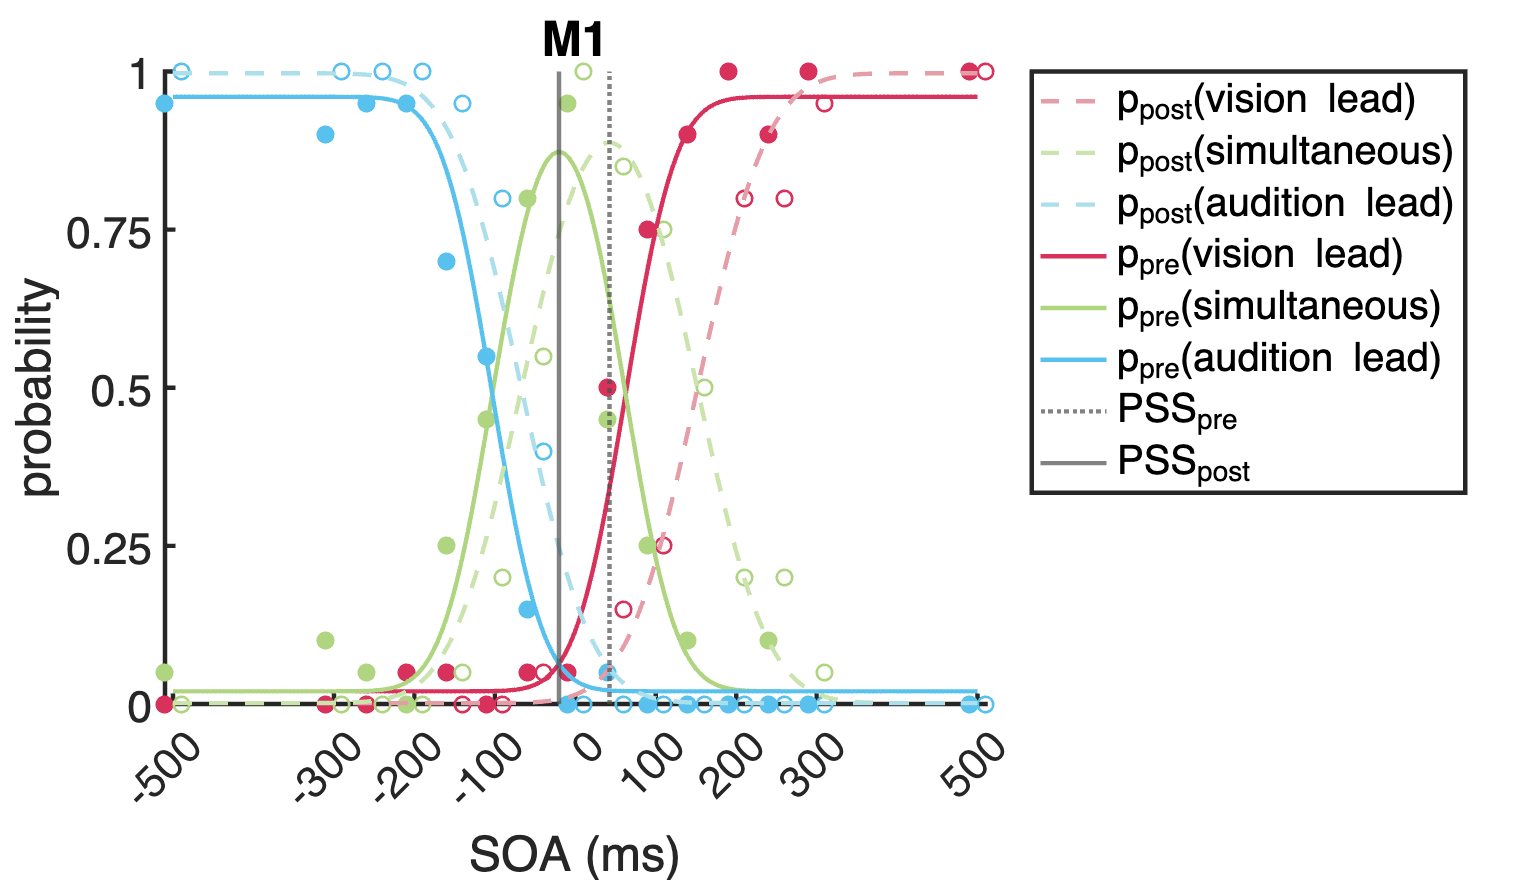

addpath(genpath('model_comparison_function'))

% plot raw data for one subject, one session
isub = 7;
isess = 7;
imodel = 1;
bestP = estP{isub}{isess, imodel};
model_comp_plotting_v5(isub, isess, imodel, bestP);

## Plot delta_mu

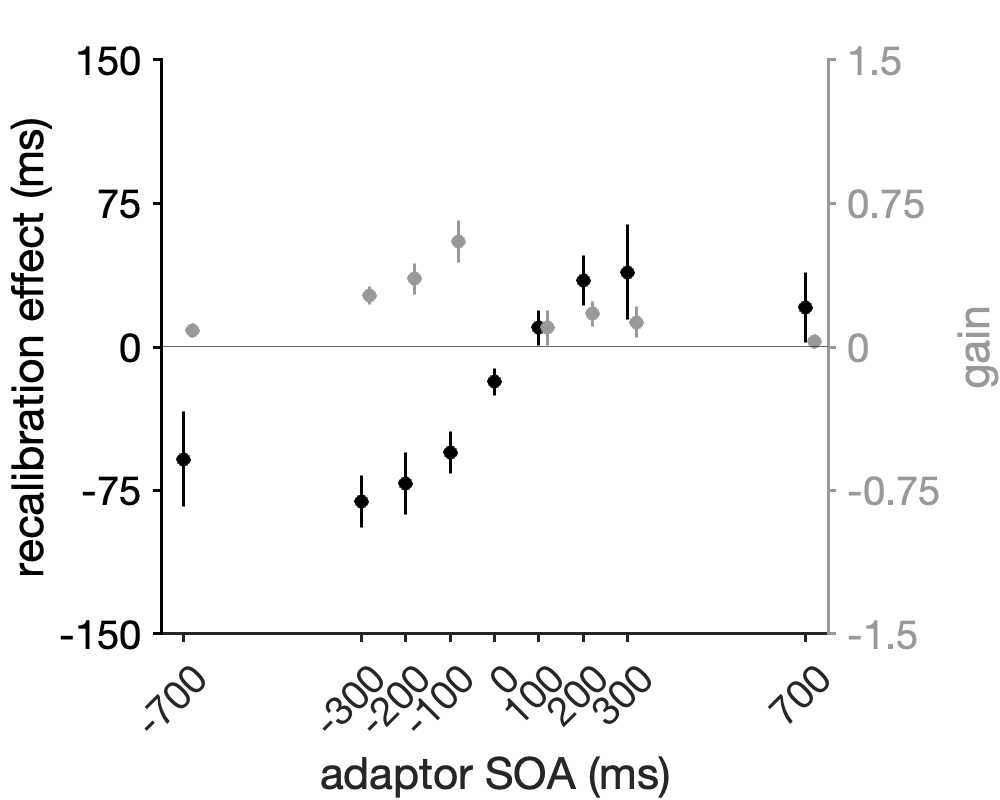

% calculate group mean
mean_delta_criterion = mean(delta_mu, 1, 'omitnan');
se_delta_criterion = std(delta_mu, [], 1, 'omitnan')./sqrt(numel(sub_slc));

% plot
figure; hold on; box off;
set(gca, 'FontSize', 20, 'LineWidth', 1.5)
set(gcf, 'Position',[10 10 500 400])
alpha = 0.6; cMAPgray = [0, 0, 0; alpha.*ones(1,3)]; colororder(cMAPgray);

yyaxis left
e = errorbar(adaptor_soa, mean_delta_criterion, se_delta_criterion, ...
    'o','LineWidth', 1.5);
e.CapSize = 0; e.MarkerFaceColor = 'k';
ylim([-150 150])
yticks(linspace(-150, 150, 5))
yline(0)
ylabel('recalibration effect (ms)')

% plot sorted gain excluding SOA=0
nnz_idx =  adaptor_soa ~= 0;
nnz_adaptor_soa = adaptor_soa(nnz_idx); 
gain = delta_mu(:,nnz_idx)./nnz_adaptor_soa;
g_gain = mean(gain, 1, 'omitnan');
sem_gain = std(gain,[],1,'omitnan')./sqrt(numel(sub_slc));

yyaxis right
e = errorbar(nnz_adaptor_soa + 20, g_gain, sem_gain, ...
    'o','LineWidth', 1.5);
e.CapSize = 0; e.MarkerFaceColor = 'auto';
ylim([-1.5 1.5])
yticks(linspace(-1.5, 1.5, 5))
ylabel('gain')

% look better
xticks(adaptor_soa)
xlim([min(adaptor_soa)-50, max(adaptor_soa)+50])
xlabel('adaptor SOA (ms)')
set(gca,'TickDir','out');

% save figure
fignm = 'fig4_delta_PSS';
saveas(gca, fullfile(outDir, fignm), 'epsc')

## plot individual pre_mu

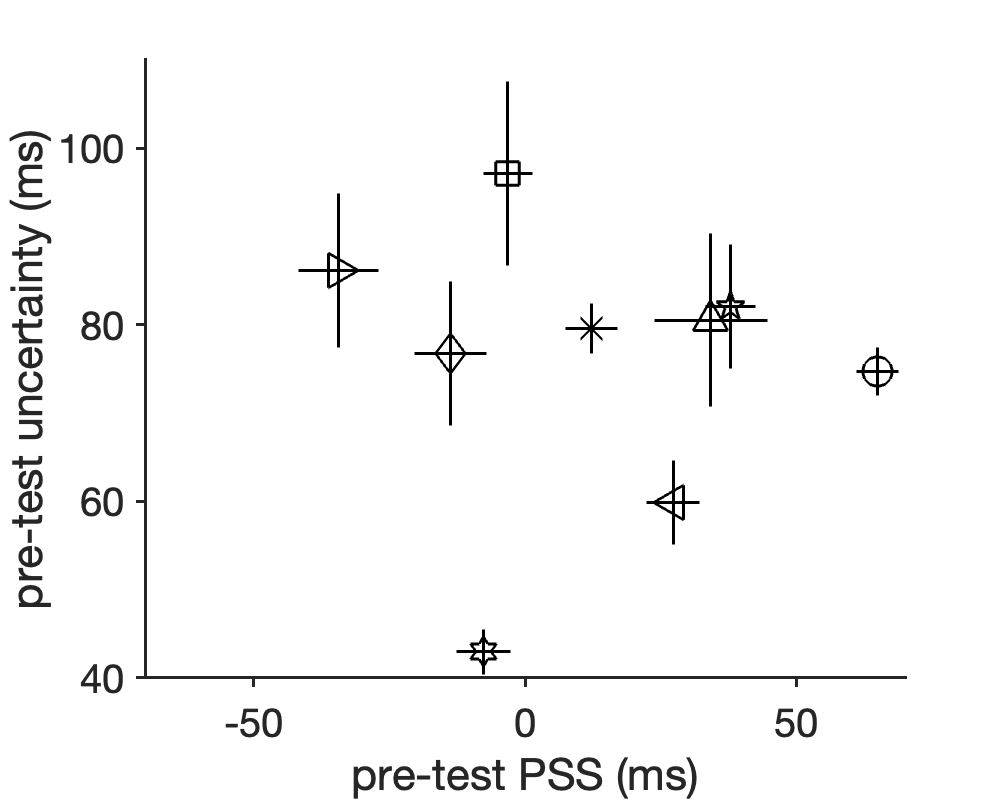

% calculate mean and se across sessions, for each individual
mean_mu_pre = mean(mu_pre, 2, 'omitnan');
se_mu_pre = std(mu_pre, [], 2, 'omitnan')./sqrt(numel(all_adaptor));
mean_sigma_pre = mean(sigma_pre, 2, 'omitnan');
se_sigma_pre = std(sigma_pre, [], 2, 'omitnan')./sqrt(numel(all_adaptor));

% plotting
figure;hold on; box off;
set(gca, 'FontSize', 20, 'LineWidth', 1.5)
set(gcf, 'Position',[10 10 500 400])
markers = ['o','s','d','^','v','>','<','p','*','h'];

for s = sub_slc
    e = errorbar(mean_mu_pre(s), mean_sigma_pre(s), ...
        se_sigma_pre(s), se_sigma_pre(s),se_mu_pre(s), se_mu_pre(s),...
    markers(s), 'LineWidth',1.5,'MarkerSize',15, 'Color','k');
    e.CapSize = 0;
end

% look better
xlim([-70, 70])
yticks([40:20:120])
xlabel('pre-test PSS (ms)')
ylabel('pre-test uncertainty (ms)')
set(gca,'TickDir','out');

% save figure
fignm = 'fig4_pre_PSS';
saveas(gca, fullfile(outDir, fignm), 'epsc')

## plot delta_sigma

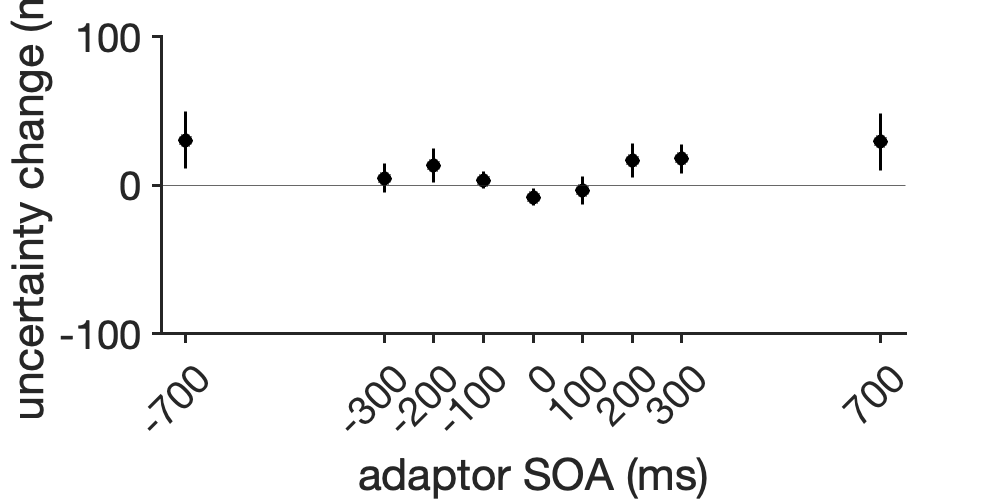

% calculate group mean
mean_delta_sigma = mean(delta_sigma, 1, 'omitnan');
se_delta_sigma = std(delta_sigma, [], 1, 'omitnan')./sqrt(numel(sub_slc));

% plot delta_mu
figure; hold on; box off;
set(gca, 'FontSize', 20, 'LineWidth', 1.5)
set(gcf, 'Position',[10 10 500 250])
alpha = 0.6; cMAPgray = [0, 0, 0; alpha.*ones(1,3)]; colororder(cMAPgray);

e = errorbar(adaptor_soa, mean_delta_sigma, se_delta_sigma, ...
    'o','LineWidth', 1.5);
e.CapSize = 0; e.MarkerFaceColor = 'auto';
ylim([-100 100])
yline(0)
ylabel('uncertainty change (ms)')

% look better
xticks(adaptor_soa)
xlim([min(adaptor_soa)-50, max(adaptor_soa)+50])
xlabel('adaptor SOA (ms)')
set(gca,'TickDir','out');

% save figure
fignm = 'fig4_delta_sigma';
saveas(gca, fullfile(outDir, fignm), 'epsc')

## plot delta_criterion

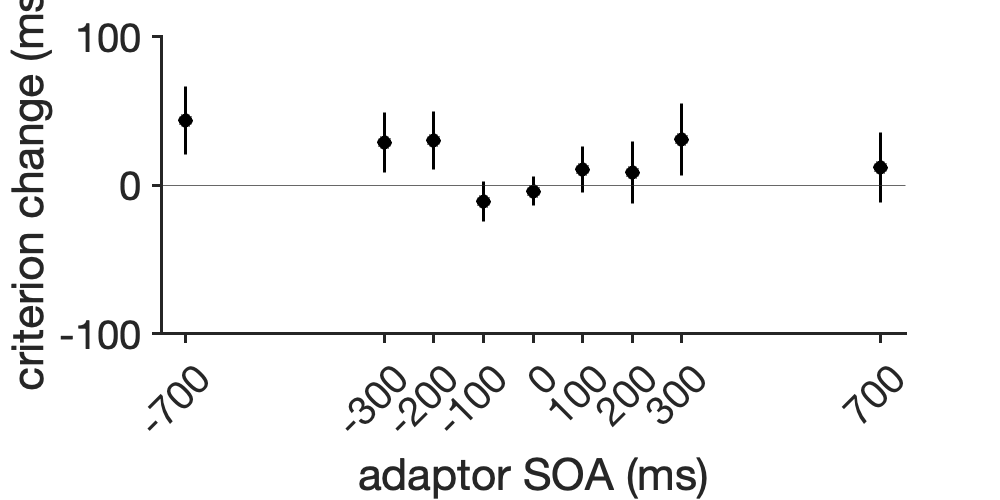

% calculate group mean
mean_delta_criterion = mean(delta_c, 1, 'omitnan');
se_delta_criterion = std(delta_c, [], 1, 'omitnan')./sqrt(numel(sub_slc));

% plot delta_mu
figure; hold on; box off;
set(gca, 'FontSize', 20, 'LineWidth', 1.5)
set(gcf, 'Position',[10 10 500 250])
alpha = 0.6; cMAPgray = [0, 0, 0; alpha.*ones(1,3)]; colororder(cMAPgray);

e = errorbar(adaptor_soa, mean_delta_criterion, se_delta_criterion, ...
    'o','LineWidth', 1.5);
e.CapSize = 0; e.MarkerFaceColor = 'auto';
ylim([-100 100])
yline(0)
ylabel('criterion change (ms)')

% look better
xticks(adaptor_soa)
xlim([min(adaptor_soa)-50, max(adaptor_soa)+50])
xlabel('adaptor SOA (ms)')
set(gca,'TickDir','out');

% save figure
fignm = 'fig4_delta_criterion';
saveas(gca, fullfile(outDir, fignm), 'epsc')